# Build Final Model and Test 

clearvars -except Data1 XTrain YTrain XTest YTest

rng default
SVMModel = fitcsvm(full(XTrain), YTrain,'Cost', [0, 1; 10, 0], 'Verbose', 1);

|===================================================================================================================================|
|   Iteration  | Set  |   Set Size   |  Feasibility  |     Delta     |      KKT      |  Number of   |   Objective   |   Constraint  |
|              |      |              |      Gap      |    Gradient   |   Violation   |  Supp. Vec.  |               |   Violation   |
|===================================================================================================================================|
|            0 |active|         7672 |  9.998697e-01 |  2.000000e+00 |  1.000000e+00 |            0 |  0.000000e+00 |  0.000000e+00 |
|         1000 |active|         7672 |  9.996711e-01 |  7.906005e+00 |  6.478175e+00 |         1870 | -5.543990e-01 |  1.307819e-18 |
|         2000 |active|         7672 |  9.994463e-01 |  4.814911e+00 |  3.624772e+00 |         3027 | -8.810697e-01 |  1.009663e-18 |
|         3000 |active|         7672 |  9.991693e-01 |  3.3811

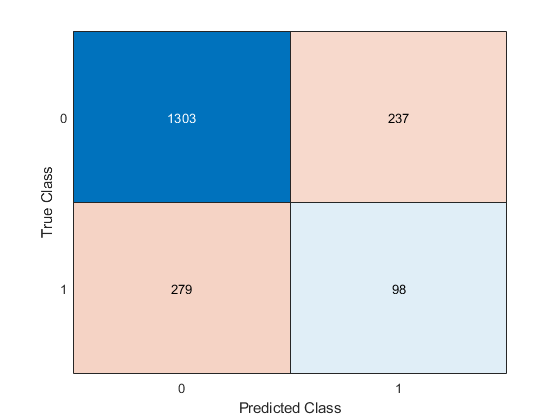

[LabelsPred, scores] = predict(SVMModel, full(XTest));
confusionchart(YTest, categorical(LabelsPred))

sum(LabelsPred == YTest)/numel(YTest)

ans = 0.7308

You can include automatic hyperparameter optimization and follow the same steps above to build and test the model.

% Mdl = fitcsvm(full(XTrain), YTrain,'Cost', [0, 1; 10, 0], 'OptimizeHyperparameters','auto',...
%     'HyperparameterOptimizationOptions',struct('UseParallel', true, 'AcquisitionFunctionName','expected-improvement-plus'))

% [LabelsPred, scores] = predict(Mdl, full(XTest));
% confusionchart(YTest, categorical(LabelsPred))
% sum(LabelsPred == YTest)/numel(YTest)